# Simulate Ear Drum

In this example, you model the response of an average human ear incorporating the lumped element impedance of both the eardrum and a portion of the ear canal. 

The model in this example follows the IEC 60318-4 Standard (formerly IEC 60711), which defines the typical human ear response up to 10 kHz. It can be integrated with other acoustic models to simulate physical measurement conditions, such as testing inserted earbuds. 

In consumer audio device evaluations, fixtures (B&K Type 4157 and GRAS RA0045) that replicate human hearing are often used, and this model provides a more accurate response.

## Open Model

Open the ear drum simulator model.

model = "EarDrumSimulator";
open_system(model);

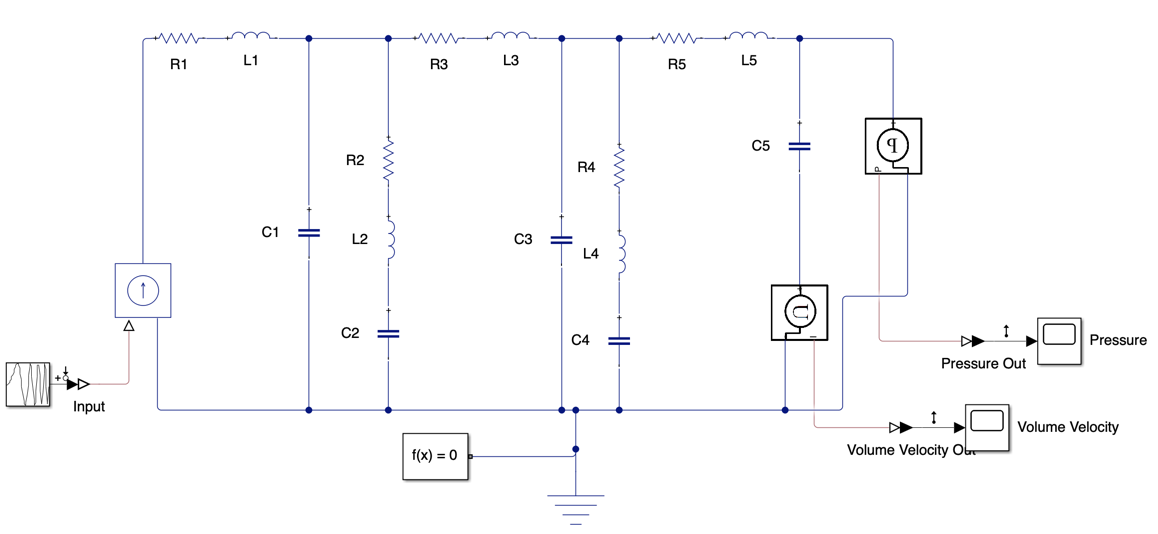

This model applies a flow source as the input so that the volume velocity plot in the linearized response is the shape of the impedance response. The output pressure is measured across the compliance labeled "C5".

Each RLC branch is intended to model the resonance frequencies in the human hearing system. The default values are directly employed from the references. Together, they simulate the response that fits the IEC60318-4 Standard limits. 

Note that R1, R3, R5 are usually not included. Their purpose is the smoothen the resonance response around 13.5kHz, which is not specified by the IEC standard. The damped response is more realistic compared to measured response (see references).

## Linearize Model

This example sets the input perturbation point and output measurement point for analysis to be done in the frequency domain instead of time domain. Extracting the real time simulation outputs and performing Fourier Transform also returns the same results. In this example, the volume velocity plot is observed.

Set the model linearizing points.

io(1) = linio("EarDrumSimulator/Chirp Signal",1, "input");              % input perturbation
io(2) = linio("EarDrumSimulator/Volume Velocity Out",1, "output");      % output volume velocity measurement

Use the `linearize` function to linearize the model and the `bode` function to extract the magnitude, phase, and frequency information. 

linsys = linearize(model,io);       % linearize model
[mag, ~, wout] = bode(linsys);      % extract results
freq = wout./(2*pi);                % convert radiance to frequency

Plot the results.

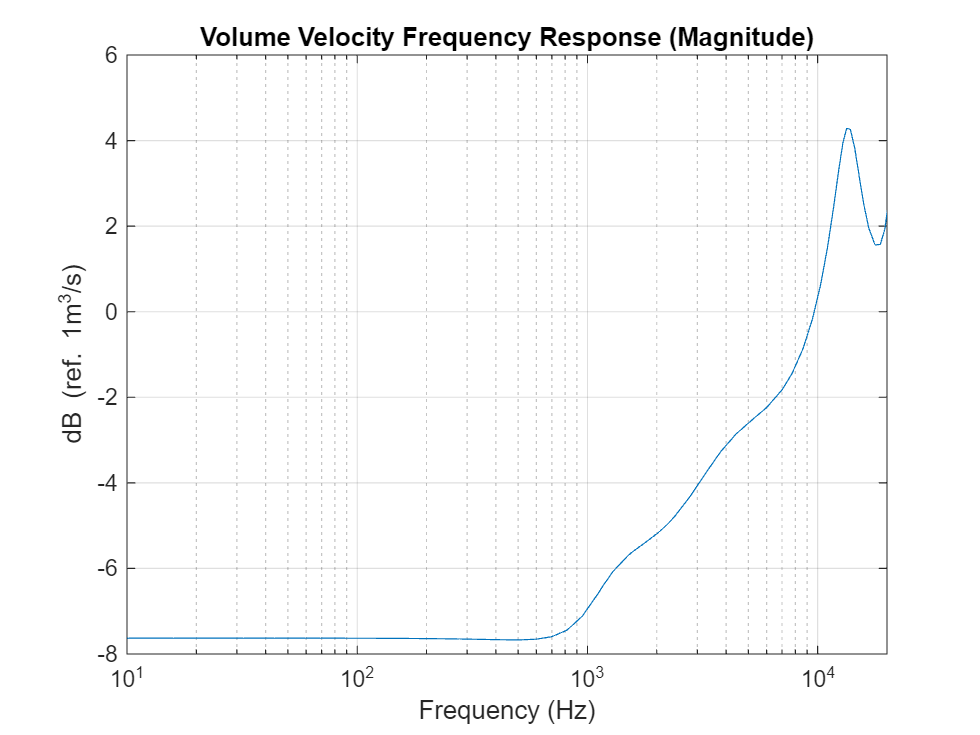

figure(1)
semilogx(freq, 10*log10(mag(:)));
xlim([10 20e3]);
title("Volume Velocity Frequency Response (Magnitude)");
xlabel("Frequency (Hz)");
ylabel("dB (ref. 1m^3/s)");
grid on
hold on

## Remove Damping

As mentioned in the previous section, most literature and simulations do not include the additional damping, naming R1, R3, and R5. In this section, these resistors are commented through for comparison. For real world measurement equipment, please refer to GRAS RA0045 and GRAS RA0401 for comparison.

path1 = model+ "/R1";
path2 = model+ "/R3";
path3 = model+ "/R5";
set_param(path1,"Commented","through");
set_param(path2,"Commented","through");
set_param(path3,"Commented","through");

Rerun the model to compare the results.

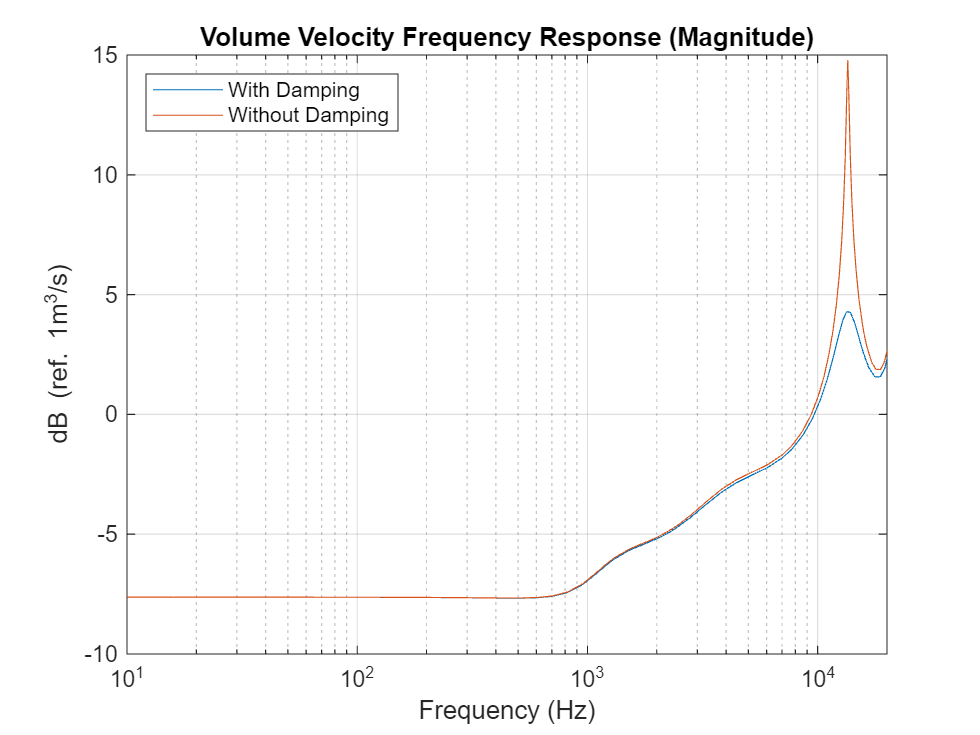

linsys = linearize(model,io);           % linearize model
[mag, ~, wout] = bode(linsys);          % extract results
freq = wout./(2*pi);                    % convert radiance to frequency

figure(1)
semilogx(freq, 10*log10(mag(:)));
xlim([10 20e3]);
title("Volume Velocity Frequency Response (Magnitude)");
xlabel("Frequency (Hz)");
ylabel("dB (ref. 1m^3/s)");
legend("With Damping", "Without Damping", 'Location','northwest');
grid on
hold on

Close the system.

bdclose(model)

## References

- Gazzola, Chiara & Zega, Valentina & Corigliano, Alberto & Lotton, Pierrick & Melon, Manuel. (2023). Lumped-Parameters Equivalent Circuit for Piezoelectric MEMS Speakers Modeling. 10.61782/fa.2023.0485.

- Gazzola, Chiara & Zega, Valentina & Corigliano, Alberto & Lotton, Pierrick & Melon, Manuel. (2024). A reduced-order-model-based equivalent circuit for piezoelectric micro-electro-mechanical-system loudspeakers modeling. The Journal of the Acoustical Society of America. 155. 1503-1514. 10.1121/10.0024939. 

*Copyright 2025 The MathWorks, Inc.*